# `Model Lotki-Volterry`

`Hubert Jackowski`

`Równanie Lotki-Volterry to model układu dynamicznego opisujący wzajemną zależność rozmiarów populacji drapieżników i ofiar. Został on zaproponowany niezależnie przez dwóch badaczy Vito Volterrę w 1926 oraz Alfreda James Lotkę w 1920 roku. [1]`

#### `MODEL`

`gdzie:`

`x - populacja ofiar,`

`y - populacja drapieżników,`

`t - czas,`

`a - częstość narodzin ofiar,`

`b - częstość umierania ofiar,`

`c - częstość narodzin drapieżników,`

`d - częstość umierania drapieżników.`

#### `SYMULACJA`

`Ustalamy zmienne wymagane do symulacji wzamejmnej zależności rozmiarów populacji drapieżników i ofiar.`

time = 20;
dt = 0.0001;
n = time / dt;
prey = linspace(2, 2, n);
predators = linspace(1, 1, n);

`Ustalamy parametry opisujące model.`

a = 1.2; b = 0.6; c = 0.3; d = 0.8;

`Symulacja zmian obu populacji.`

for i=2:1:n
    tempPrey = prey(i-1);
    tempPredators = predators(i-1);
    prey(i) = tempPrey + (a - b * tempPredators) * tempPrey * dt;
    predators(i) = tempPredators + (c * tempPrey - d) * tempPredators * dt;
end

`Utworzenie wykresu zmiany populacji drapieżników i ofiar w czasie.`

plot(prey, color="#138a2b")
hold on
plot(predators, color="#cc0e2b")
set(gca, 'XTick', 0:5/dt:n, 'XTickLabel', 0:5:time)
title('Model Lotki-Volterry') 
ylabel('Liczba osobników') 
xlabel('Okresy lęgowe')

#### `OBSERWACJE`

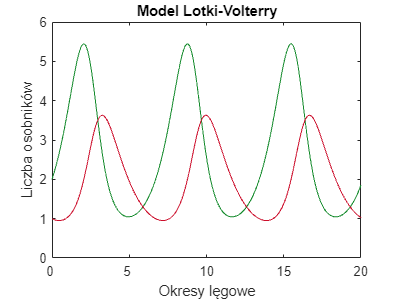

`Figure 1: Rezultat symulacji kolorem czerwonym zaznaczono populację drapieżników, a kolorem zielonym populację ofiar.`

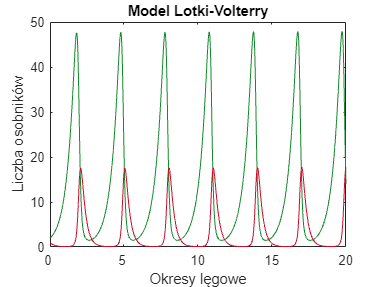

`Figure 2: Rezultat symulacji dla zmienionych wartości parametrów modelu wyjściowego Lotki-Volterry (a = 2, b = 0.6, c = 0.3, d = 4) kolorem czerwonym zaznaczono populację drapieżników, a kolorem zielonym populację ofiar.`

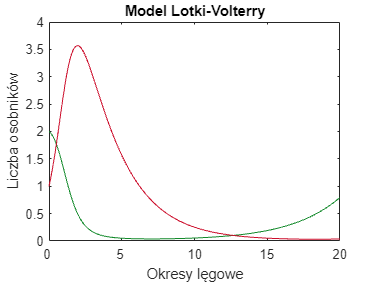

`Figure 3: Rezultat symulacji dla zmienionych wartości parametrów modelu wyjściowego Lotki-Volterry (a = 0.3, b = 0.4, c = 0.8, d = 0.4) kolorem czerwonym zaznaczono populację drapieżników, a kolorem zielonym populację ofiar.`

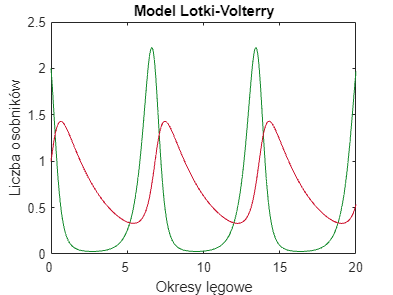

`Figure 4: Rezultat symulacji dla zmienionych wartości parametrów modelu wyjściowego Lotki-Volterry (a = 3, b = 4, c = 0.8, d = 0.4) kolorem czerwonym zaznaczono populację drapieżników, a kolorem zielonym populację ofiar.`

#### `WNIOSKI`

`Zauważmy, że liczebność populacji drapieżników jest ściśle związana z liczebnością populacji ofiar. Spadek populacji ofiar skutkuje zmniejszeniem populacji drapieżników. Ta zmiana skutkuje natomiast stworzeniem okoliczności, w której niezagrożona populacja ofiar wzrasta i cykl się powtarza, co zauważamy na wykresach przeprowadzonych symulacji [Figure 1-4].`

#### `LITERATURA`

`[1] J.D. Murray: Wprowadzenie do Biomatematyki. Warszawa: Wydawnictwo Naukowe PWN, 2006. ISBN 83-01 14719-9.`